# Procedure 1 for Acrobot system

clear; close all; clc;
set(0,'DefaultLineLineWidth',2.5) 
set(0,'defaultfigurecolor',[1 1 1])

## 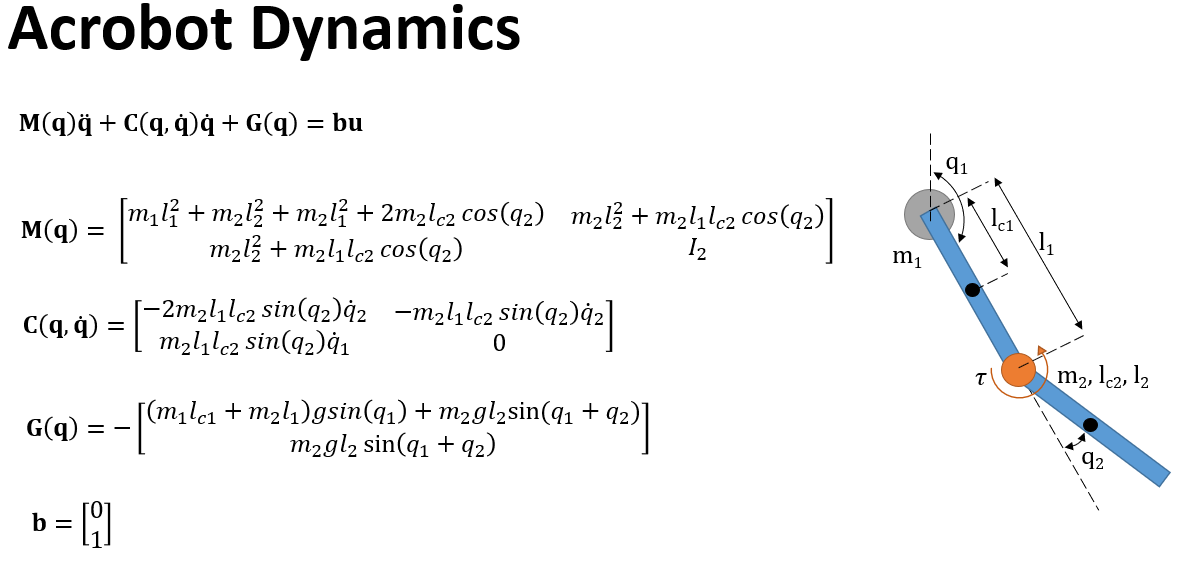

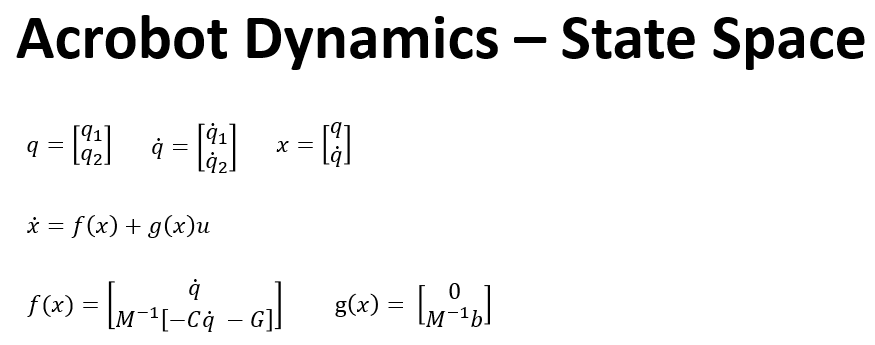

f = @Acrobot_F;
g = @Acrobot_g;

## 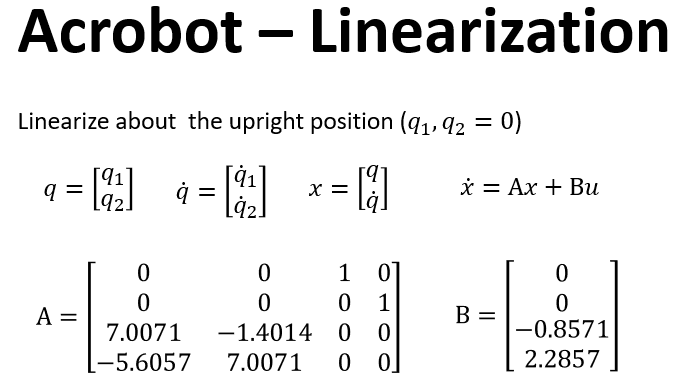

n=4; % dimension
x = sym('x',[n;1]);
u = sym('u',[1;1]);
x0 = [1;1;1;1];

A = double(subs(jacobian(f(0,x,0),x),x,x0)); 
B = double(subs(jacobian(f(0,x0,u),u),u,0));
%linear eigenfunctions realization from complex eigenfunctions
[~,D1,W1] = eig(A);
[W, D] = cdf2rdf(W1, D1);

## Parameters setup

Dom1 = [-2*pi 2*pi]; %Domain for q1 q2
Dom2 = [-10 10]; %Domain for q1_dot q2_dot
domain1 = Dom1(2)-Dom1(1);
domain2 = Dom2(2)-Dom2(1);

## Collect random initial conditions

% numICs = 1e4; %initial coditions
% X1 = (rand(2,numICs)*2*Dom1(2) - Dom1(2));
% X2 = (rand(2,numICs)*2*Dom2(2) - Dom2(2));
% X=[X1;X2];

## Try some initial conditions and collect X along trajectories 

Skip this if you run the previous section and generated random initial condtions

numICs = 1000;

x1range = Dom1; %q1
x2range = Dom1; %q2
x3range = Dom2; %q1_dot
x4range = Dom2; %q2_dot
tSpan = 0:0.2:10;
seed = 1;

rng(seed)

lenT = length(tSpan);

X = zeros(lenT, n);

count = 1;
for j = 1:100*numICs
    % randomly start from x1range(1) to x1range(2)
    x1 = (x1range(2)-x1range(1))*rand+x1range(1);
    x2 = (x2range(2)-x2range(1))*rand+x2range(1);
    x3 = (x3range(2)-x3range(1))*rand+x3range(1);
    x4 = (x4range(2)-x4range(1))*rand+x4range(1);

    ic = [x1; x2; x3; x4];
    [T, temp] = ode45(@(t,x)f(0, x, 0), tSpan, ic);
    X(1+(count-1)*lenT : lenT + (count-1)*lenT,:) = temp;
    if count == numICs
        break
    end
    count = count + 1;
end
X=X';

## Selet basis functions to approximate h(x)

order = 3; %order poly
TrigTerms = 0;
[Psi, DPsi] = monomial_basis(order, n, TrigTerms);

$$Psi = \left(\begin{array}{cccccccccccccccccccccccccccccccccc} x_{1} & x_{2} & x_{3} & x_{4} & {x_{4}}^{2} & x_{3}\,x_{4} & {x_{3}}^{2} & x_{2}\,x_{4} & x_{2}\,x_{3} & {x_{2}}^{2} & x_{1}\,x_{4} & x_{1}\,x_{3} & x_{1}\,x_{2} & {x_{1}}^{2} & {x_{4}}^{3} & x_{3}\,{x_{4}}^{2} & {x_{3}}^{2}\,x_{4} & {x_{3}}^{3} & x_{2}\,{x_{4}}^{2} & x_{2}\,x_{3}\,x_{4} & x_{2}\,{x_{3}}^{2} & {x_{2}}^{2}\,x_{4} & {x_{2}}^{2}\,x_{3} & {x_{2}}^{3} & x_{1}\,{x_{4}}^{2} & x_{1}\,x_{3}\,x_{4} & x_{1}\,{x_{3}}^{2} & x_{1}\,x_{2}\,x_{4} & x_{1}\,x_{2}\,x_{3} & x_{1}\,{x_{2}}^{2} & {x_{1}}^{2}\,x_{4} & {x_{1}}^{2}\,x_{3} & {x_{1}}^{2}\,x_{2} & {x_{1}}^{3} \end{array}\right)$$

%[Psi, DPsi] = bernstein_basis(order, n, 1);
Psi = Psi(n+1:end); %remove linear part
Nbs = length(Psi);

x1 = sym('x',[n,1]);
DPsi = jacobian(Psi,x1);

Psi = matlabFunction(Psi,'Vars',{x1});
DPsi = matlabFunction(DPsi,'Vars',{x1});

## Solve the least squares problem to estimate U

E = A;
Ez = E*X; 
G_z = Psi(X);

F_z = [];
for i=1:size(X,2)
    F_z = [F_z, f(0, X(:,i), 0)];
end

Df_z = zeros(Nbs,1);
for i=1:size(X,2)
    Df_z(:,i) = DPsi(X(:,i))*f(0, X(:,i), 0);
end

%YALMIP
params.NumericFocus=1;
aa = 0.1; %regularization
U = sdpvar(n,Nbs);
obj = U*Df_z + F_z - A*U*G_z - Ez;

Objective =  norm(U*Df_z + F_z - A*U*G_z - Ez, 'fro') + aa*norm(U,1);
Constraints = [];
opt = sdpsettings('solver','mosek','verbose',2,'cachesolvers',1,'showprogress',1);
sol = optimize(Constraints,Objective,opt);

+ Solver chosen : MOSEK-SOCP
+ Processing objective function
+ Processing constraints
+ Calling Mosek

MOSEK Version 9.3.18 (Build date: 2022-3-17 11:29:16)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

MOSEK warning 710: #1 (nearly) zero elements are specified in sparse col '' (182087) of matrix 'A'.
MOSEK warning 710: #1 (nearly) zero elements are specified in sparse col '' (182088) of matrix 'A'.
MOSEK warning 710: #2 (nearly) zero elements are specified in sparse col '' (182089) of matrix 'A'.
MOSEK warning 710: #2 (nearly) zero elements are specified in sparse col '' (182090) of matrix 'A'.
Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 242             
  Cones                  : 1               
  Scalar variables       : 204271          
  Matrix variables       : 0               
  Integer variables      : 0      

U = value(U);

## Eigenfunctions of the original system

% nonlinear eigenfuncitons without scaling
Phi = @(x) W'*x + W'*U*Psi(x);
DPhi = @(x) W' + W'*U*DPsi(x);

% nonlinear eigenfuncitons with scaling
%scale = @(x) x /(Dom(2)-Dom(1));
%Phi = @(x) W'*scale(x) + W'*scale(hat_h*Psi(x));
%DPhi = @(x) W' + W'*scale(hat_h*DPsi(x));

## LQR Controller

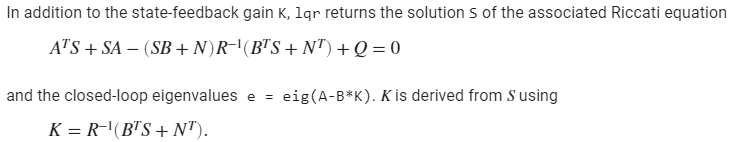

 

Compare matlab's Riccati equation for LQR, we get R_koopman = B_tranpose*inv(R_lqr)*B

Q = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]; %cost on states
R_lqr = 1;
[K,P,CLP] = lqr(A,B,Q,R_lqr);
uLQR = @(x) -K*(x);

## HJ-Koopman Controller:

Where,

R_Koopman = B*inv(R_lqr)*B';
hat_R = W'*(R_Koopman)*W;
W1_inv = inv(W);
hat_Q = W1_inv*Q*W1_inv';
L = are(D,hat_R,hat_Q);
uKoop=@(x) -Phi(x)'*L*DPhi(x)*g(0,x);

## Sanity Check 

L1 should be equal to P

L1 = W*L*W'

L1 = 	1.0e+03 *

    8.6509    2.5006    3.9095    1.3793
    2.5006    0.7336    1.1318    0.4027
    3.9095    1.1318    1.7674    0.6241
    1.3793    0.4027    0.6241    0.2216


P

P = 	1.0e+03 *

    8.6509    2.5006    3.9095    1.3793
    2.5006    0.7336    1.1318    0.4027
    3.9095    1.1318    1.7674    0.6241
    1.3793    0.4027    0.6241    0.2216


## Simulation

(change x_initial to simulate response of different initial conditions and plot)

deltaT = 0.01; %step-time
tspan = 0:deltaT:10;
options = odeset('RelTol',1e-9,'AbsTol',1e-300);
x_initial = [0.01,0,0,0];

%LQR
[tspan, xLQR] = ode45(@(t,x)f(t, x, uLQR(x)), tspan, x_initial, options);

if(abs(xLQR(end,1)) && abs(xLQR(end,3)) <=1e-3)
    disp('LQR succuess')
else
    disp('LQR failed')
end

LQR succuess


[tspan1, x_Koop] = ode45(@(t,x)f(t, x, uKoop(x)), tspan, x_initial, options);
if(abs(x_Koop(end,1)) && abs(x_Koop(end,3)) <=1e-3)
   disp('HJK succuess')
else
   disp('HJK failed')
end

HJK succuess


## Plots

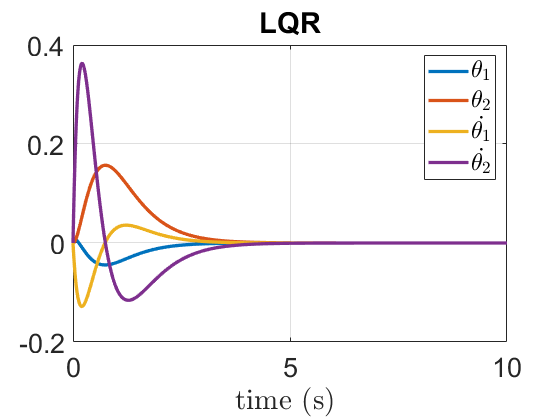

close all
figure(1)
%subplot(2,2,1)
plot(tspan, xLQR)
grid on;
title('LQR')
xlabel('time (s) ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$\theta_1$', '$\theta_2$', '$\dot{\theta_1}$','$\dot{\theta_2}$');
set(LEG,'interpreter','latex')

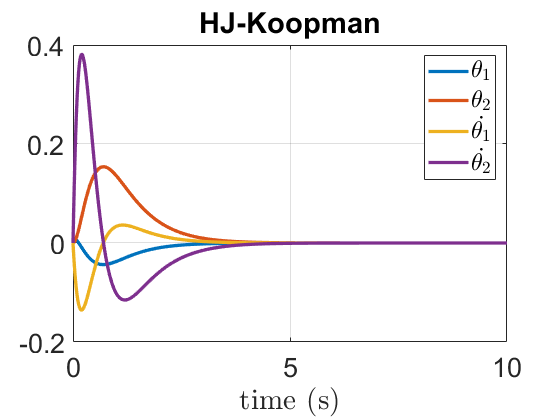

figure(2)
%subplot(2,2,2)
plot(tspan1, x_Koop)
grid on;
title('HJ-Koopman')
xlabel('time (s)','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$\theta_1$', '$\theta_2$', '$\dot{\theta_1}$','$\dot{\theta_2}$');
set(LEG,'interpreter','latex')

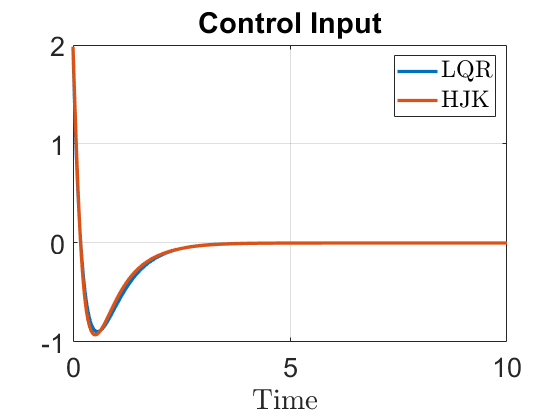

figure(3)
%subplot(2,2,3)
 U_Lqr =zeros(size(xLQR,1),1);
 U_Koop = zeros(size(xLQR,1),1);
for i=1:size(xLQR,1)
    U_Lqr(i) = uLQR(xLQR(i,:)');
    U_Koop(i) =uKoop(x_Koop(i,:)');
end
%plot(tspan, U_Lqr)
plot(tspan, U_Lqr, tspan1, U_Koop)
grid on;
title('Input')
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('LQR','HJK');
set(LEG,'interpreter','latex')
title('Control Input')

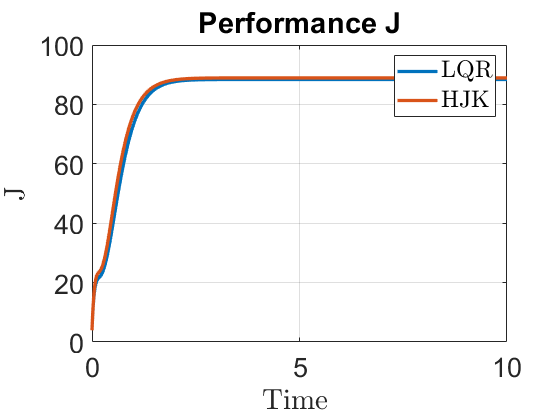

figure(4)
%subplot(2,2,4)
JLQR = cumsum(xLQR(:,1).^2 + xLQR(:,2).^2 + xLQR(:,3).^2 + xLQR(:,4).^2 + U_Lqr.^2);
Jkoopman =  cumsum(x_Koop(:,1).^2 + x_Koop(:,2).^2 + x_Koop(:,3).^2 + x_Koop(:,4).^2  +U_Koop.^2 );

plot(tspan, JLQR,tspan, Jkoopman)
grid on;
title('Performance J')
set(gca,'fontsize',20)
LEG =legend( 'LQR','HJK');
ylabel('J','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(LEG,'interpreter','latex')

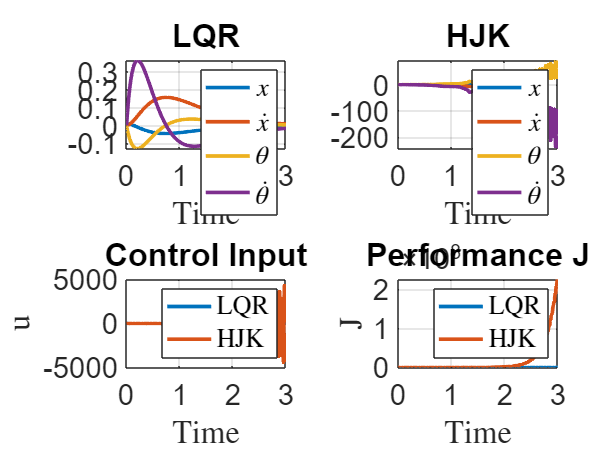

close all
subplot(2,2,1)
plot(tspan1, xLQR)
grid on; hold on;
%legend('x_1', 'x_2');xlabel('Time')
title('LQR')
xlabel('Time ','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend( '$x$', '$\dot{x}$', '$\theta$', '$\dot{\theta}$');
set(LEG,'interpreter','latex')

subplot(2,2,2)
plot(tspan1, x_Koop)
grid on;
title('HJK')
xlabel('Time','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend( '$x$', '$\dot{x}$', '$\theta$', '$\dot{\theta}$');
set(LEG,'interpreter','latex')

subplot(2,2,3)
 U_Lqr =zeros(size(xLQR,1),1);
 U_Koop = zeros(size(xLQR,1),1);
for i=1:size(xLQR,1)
    U_Lqr(i) = uLQR(xLQR(i,:)');
    U_Koop(i) =uKoop(x_Koop(i,:)');
end
plot(tspan, U_Lqr, tspan1, U_Koop)
grid on;
title('Input')
ylabel('u','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('LQR','HJK');
set(LEG,'interpreter','latex')
title('Control Input')

subplot(2,2,4)
JLQR = cumsum(xLQR(:,1).^2 + xLQR(:,2).^2 + xLQR(:,3).^2 + xLQR(:,4).^2 + U_Lqr.^2);
Jkoopman =  cumsum(x_Koop(:,1).^2 + x_Koop(:,2).^2 + x_Koop(:,3).^2 + x_Koop(:,4).^2  +U_Koop.^2 );
%plot(tspan, JLQR,)
plot(tspan, JLQR,tspan, Jkoopman)
grid on;
title('Performance J')
set(gca,'fontsize',20)
LEG =legend( 'LQR','HJK');
ylabel('J','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(LEG,'interpreter','latex')

## Acrobot f(x)

function f = Acrobot_F(t, x, u)
m1 = 1 ; m2 = 1;
l1 = 1 ; l2 = 1;g = 9.81;
lc1 = l1/2; lc2 = l2/2;
I1 = 1 ;I2 = 1; 
q1 = x(1,:); q2 = x(2,:); dq1 = x(3,:); dq2 = x(4,:);

m11 = I1 + I2 + m2*l1^2 + 2*m2*l1*lc2.*cos(q2);
m12 = I2 + m2*l1*lc2.*cos(q2);
m22 = I2*ones(1,size(x,2));
M = [m11 m12; m12 m22];

C = [-2*m2*l1*lc2.*sin(q2).*dq2.*dq1-m2*l1*lc2.*sin(q2).*dq2.*dq2;
     m2*l1*lc2.*sin(q2).*dq1.*dq1+zeros(1, size(x,2)).*dq2];

% G is negative for q1 = 0  about vertical
% G is positive for q1 = pi about vertical
G = -[m1*g*lc1.*sin(q1) + m2*g.*(l1.*sin(q1)+lc2.*sin(q1+q2));
     m2*g*lc2.*sin(q1+q2)];

dq = [dq1; dq2]; B1 = [zeros(1,size(x,2)); ones(1,size(x,2))];

ddq = M\(B1.*u-C-G);
f = [dq;ddq];
end

## Acrobot g(x)

function g = Acrobot_g(t, x)
m1 = 1 ; m2 = 1;
l1 = 1 ; l2 = 1;g = 9.81;
lc1 = l1/2; lc2 = l2/2;
I1 = 1 ;I2 = 1; 
q1 = x(1,:); q2 = x(2,:); dq1 = x(3,:); dq2 = x(4,:);

m11 = I1+ I2 + m2*l1^2 + 2*m2*l1*lc2*cos(q2);
m12 = I2 + m2*l1*lc2*cos(q2);
m22 = I2;
M = [m11 m12 ; m12 m22];
B1 = [0;1];

g = [0;0; M\(B1)];
end

## Monomial Basis

function [Psi, DPsi] = monomial_basis(deg, dim, TrigTerms)
%  [Psi, DPsi] = monomial_basis(deg, dim) returns a monomial basis function and its derivative 
%   There is not a 1 included in Psi, only the linear and higher order terms
%   deg = degree of monomial
%   dim = number of states
k = linspace(2, deg, deg-1);
d = dim;

if nargin<3
  TrigTerms = 0;
end


if (deg == 0)
    Psi = 0;
    for i=1:dim-1
        Psi = [Psi 0];
    end
    DPsi = zeros(dim,dim);
    Psi = Psi';
    
else

    x=sym('x',[d,1]);
    assume(x,'real')
    
    Psi = [x.'];
    for i=1:size(k,2)
        m = nchoosek(k(i)+d-1,d-1); 
        dividers = [zeros(m,1),nchoosek((1:(k(i)+d-1))',d-1),ones(m,1)*(k(i)+d)]; 
        a = diff(dividers,1,2)-1;
        for i = 1:size(a,1)
            Psi = [Psi prod(x.' .^ a(i,:))];
        end
    end
    DPsi = jacobian(Psi,x);
    
 
if(TrigTerms==1)
    Trig_terms = [];
    for j=1:dim
        Trig_terms = [Trig_terms sin(x(j)) cos(x(j))];
    end 

    % Using trig terms for acrobot gives bad results compared to LQR
    %Psi = [Psi Trig_terms sin(x(1)+x(2)) cos(x(1)+x(2))];
    Psi = [Psi Trig_terms];
end

    Psi %disp Psi
    Psi = Psi';

end

end

## Bernstein Basis

function [Psi,DPsi] = bernstein_basis(order, dim, scale)
%  [Psi, DPsi] = bernstein_basis(deg, dim,scale=0) returns a bernstein basis function and its derivative 
%   There is not a 1 included in Psi, only the linear and higher order terms
%   order = order of bernstein polynomials being fit
%   dim = number of states

if nargin<3
  scale = 0;
end

x=sym('x',[dim,1]);
assume(x,'real')
Psi = [];

if(order==0)
    Psi = 1;
end

for i = 0:order
    m = nchoosek(order,i);
    for j = 1:dim
        %Psi = [Psi; m.*((x(j)+1).^i * (-x(j)).^(order-i))];
        %scale to -2pi to 2pi
        Psi = [Psi; m.*((x(j)+scale).^i * (1-scale-x(j)).^(order-i))];
    end
end
Psi' %display Psi
DPsi = jacobian(Psi,x);

end